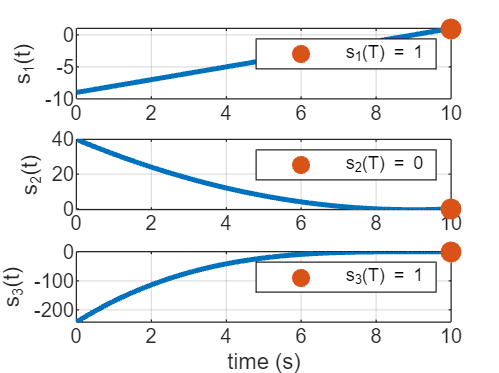

clear all; clc; close all;

S_T = eye(2);
Q = eye(2);
A = [0 1; -1 -1];
T = 10;

[t,S] = ode45(@riccati,[0 T],[1 0 1]);

% need to go forwards in time
N = length(t);
for i = 1:N
    index = N+1-i;
    t_forward(i) = T-t(index);
    S_f(i,:,:) = [S(index,1) S(index,2);
                    S(index,2) S(index,3)];
end
% plotting components of S(t)
img = figure(1);
subplot(3,1,1)
plot(t_forward,S_f(:,1,1),'LineWidth',2)
hold on
plot(t_forward(end),S_f(end,1,1),'.','MarkerSize',25)
gravstr = sprintf('s_1(T) = %d',S_f(end,1,1));
legend('', gravstr)
ylabel('s_1(t)')
grid on


subplot(3,1,2)
plot(t_forward,S_f(:,1,2),'LineWidth',2)
hold on
plot(t_forward(end),S_f(end,1,2),'.','MarkerSize',25)
gravstr = sprintf('s_2(T) = %d',S_f(end,1,2));
legend('', gravstr)
ylabel('s_2(t)')
grid on

subplot(3,1,3)
plot(t_forward,S_f(:,2,2),'LineWidth',2)
hold on
plot(t_forward(end),S_f(end,2,2),'.','MarkerSize',25)
gravstr = sprintf('s_3(T) = %d',S_f(end,2,2));
legend('', gravstr)
xlabel('time (s)')
ylabel('s_3(t)')
grid on